# **Time Series Analysis**

Stock prices, daily temperatures and pressures (called **signals**) are reported across a given time period where one can identify trends and perform analysis on time series datasets. Here we provide you with a simple time-series datasets (bunch of numbers along a time period) to boadly determine the overall trends visually through plotting figures.  

clc; clear;

## Load CSV Dataset

Read **Data.csv **into the variable `signal`. Determine its length (n) using the `length() `function. Do NOT hand-type the array length; you will lose points here.

signal = ?;
signal = signal*1000
n = ?

### Determine rate of change

Remember Calc I? There is a simple idea of determining the rate of change between two points (slope) by finding the ratio of the ***rise ***to ***run. ***The rise is the difference of two adjacent values of the signal; the run in this case is 2t; t=1. 

We will now "walk" through each point in the signal array using the FOR-loop to determine the slope at that point. There are a few questions to answer first

- What is the first index of i in the for-loop? Is it 1? If not, then why?

- What is the last index of i in the for-loop? Is it n?

- What is the size of the `slope` array? Is it the same as that of `signal`?

Draw a test array (5 elements) on a paper, label the indices (1,2,..5), fill out the first five values of signal. Work out the slopes at these five (?) points. Test out your idea in another script. They should match your results on paper.  Do not proceed further before doing working on paper.

### Anamoly detection using slopes

Next we also find that our signal is not entirely "clean", meaning there are outliers in our signal that were incorrectly measured. We have a way to "detect" these outliers: if the slope between two points exceed 150, then the value at that location (i) is an outlier and therefore needs to be tossed out. There is nothing "scientific" about this rule: we just made one here. We will then save only the "clean" values to a new array `new_signal` to the CSV output. 

for i = ?:?
    slope(i) = ?
    
    if (?)
        new_signal(i) = ?
??
??

NOTE: As the size of `slope` and `new_signal `will change after each iteration. Matlab has a way to take care of that: it automatically resizes and expands the array during execution.   

% Determine the length of new_signal using the length() function.
n_clean = ?

### Trend detection

After "cleaning up" our dataset, we turn our attention towards determining trends. If you have been paying attention to COVID-19 stats, there is a trendline that goes by the name of "moving average". They help scientists predict trends in cases over a period of time, since daily numbers can vary by large amounts; sometimes having outliers in the reported numbers. We are trying to do something similar here. 

A three-point moving average at a given point is computed by taking the average values of two neighboring points on either side and the central point. 

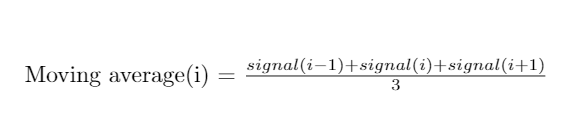

This formulation would only work in the "interior" of the array. See previous lectures to understand the term "interior". Q: Is this equation applicable at the endpoints? The answer is NO. And if this looks new to you, then please prepare yourself to see such formualations in future numerical methods, signal processing, CFD courses. They will have you work with one set of equation for the interior, and another set of equations at the endpoints.  

At the right endpoint, there is no point avaiable on the right; at the left endpoint, there is no point available on the left. Therefore use the two points avaiable to compute averages at the endpoints. NOTE: you won't divide by 3, but 2 here. 

Therefore we have three options within the FOR-loop: the interior, the left endpoint and the right endpoint. You are required to use the IF-ELSEIF block within the FOR-loop.

for ?
    if ?
        ?
    elseif ?
        ?
    else
        moving_avg(i) = ?;
    end
end


NOTE: As the size of `moving_avg `will change after each iteration. Matlab has a way to take care of that: it automatically resizes and expands the array during execution.   

#### Plot results

figure()
x  =?
plot(?, ); % blue dot
hold on;
plot(?, ); % black line